# Creating Map Displays with Data in Projected Coordinate Reference System

This example illustrates how to import and display geographic data that contain coordinates in a projected coordinate reference system. 

In particular, this example illustrates how to

- Import specific raster and vector data sets

- Create map displays for visualizing the data

- Display multiple data sets in a map display

- Display multiple data sets with coordinates in geographic and projected coordinate reference systems in a single map display

## Example 1: Import Raster Data in Projected Coordinate Reference System

Geographic raster data that contains coordinates in a projected coordinate reference system can be stored in a variety of different formats, including standard file formats such as GeoTIFF, Spatial Data Transfer Standard (SDTS), NetCDF, HDF4, or HDF5. This example illustrates importing data from a GeoTIFF file. The data in the file contains coordinates in the projected map coordinate reference system *Massachusetts State Plane Mainland Zone coordinate system*.

The coordinates of the image in the GeoTIFF file, `boston.tif`, are in a projected coordinate reference system. You can determine that by using the `geotiffinfo` function and examine the `PCS` and `Projection` field values.

info = geotiffinfo('boston.tif');
disp(info.PCS)

NAD83 / Massachusetts Mainland


disp(info.Projection)

SPCS83 Massachusetts Mainland zone (meters)


The length unit of the coordinates are defined by the `UOMLength` field in the `info` structure.

disp(info.UOMLength)

US survey foot


To import the image and the spatial referencing object, use `geotiffread`.

[boston, R] = geotiffread('boston.tif');

## Example 2: Display Raster Data in Projected Coordinate Reference System

You can display the image on a regular MATLAB axes using `mapshow`, which displays the image and sets the axes limits to the limits defined by the referencing object, `R`. The coordinates, as mentioned above, are in `US survey foot` and are relative to an origin to the southwest of the map, which is why the numbers are large. The coordinates are always positive within the zone.

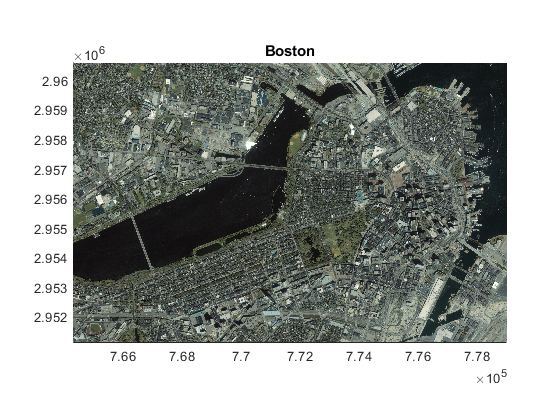

mapshow(boston, R)
axis image
title('Boston')

## Example 3: Import Vector Data in Projected Coordinate Reference System

Geographic vector data that contains coordinates in a projected coordinate reference system can be stored in shapefiles. This example illustrates how to import vector data in a projected coordinate reference system from the shapefile, `boston_roads.shp`. In general, shapefiles contain the projection information in an auxiliary .prj file. This file is not included with the Mapping Toolbox™ software for `boston_roads`. However, you can determine the coordinate reference system from the `boston_roads.txt` file that is included with the Mapping Toolbox™ software which states, *"All data distributed by MassGIS are registered to the NAD83 datum, Massachusetts State Plane Mainland Zone coordinate system. Units are in meters."*

Import vector line data from the `boston_roads.shp` file included with the Mapping Toolbox™ software.

roads = shaperead('boston_roads');

## Example 4: Display Vector and Raster Data in Projected Coordinate Reference System

The vector and raster data in this example are in the same projected coordinate reference system, *Massachusetts State Plane Mainland Zone*. However, the vector data is in length units of meter, while the raster data is in length unit of survey foot. Convert the raster data to length units of meter and display the data on the same axes.

Convert the coordinates of the raster image from units of US survey foot to meter. 

R.XWorldLimits = R.XWorldLimits * unitsratio('m','sf');
R.YWorldLimits = R.YWorldLimits * unitsratio('m','sf');

Display the raster image and vector data using `mapshow`.

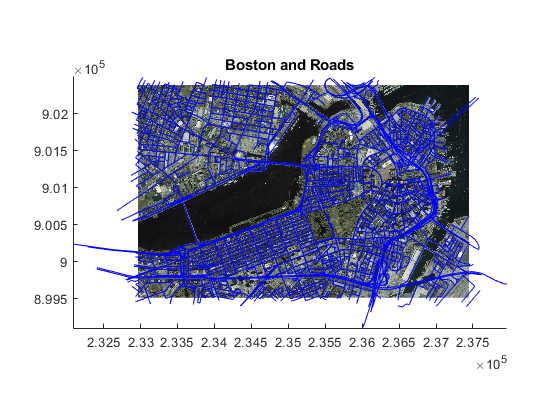

figure
mapshow(boston, R)
mapshow(roads)
title('Boston and Roads')

## Example 5: Display Data in both Geographic and Projected Coordinate Reference Systems

You may have geographic data whose coordinates are in latitude and longitude and other data whose coordinates are in a projected coordinate reference system. You can display these data sets in the same map display. This example illustrates how to display data in a geographic coordinate reference system (latitude and longitude) with data in a projected map coordinate reference system (Massachusetts State Plane Mainland Zone coordinate system).

Read a raster image with a worldfile whose coordinates are in latitude and longitude. Use `imread` to read the image and `worldfileread` to read the worldfile and construct a spatial referencing object.

filename = 'boston_ovr.jpg';
overview = imread(filename);
overviewR = worldfileread(getworldfilename(filename), 'geographic', size(overview));

To display the overview image and the GeoTIFF image in the same map display, you need to create a map display using a Mapping Toolbox™ projection structure containing the projection information for the data in the projected coordinate reference system, *Massachusetts State Plane Mainland Zone coordinate system*. To make a map display in this system, you can use the projection information contained in the GeoTIFF file. Use the `geotiff2mstruct` function to construct a Mapping Toolbox™ projection structure, from the contents of the GeoTIFF information structure. The `geotiff2mstruct` function returns a projection in units of meters. Use the projection structure to define the projection parameters for the map display.

mstruct = geotiff2mstruct(info);

Use the latitude and longitude limits of the Boston overview image.

latlim = overviewR.LatitudeLimits;
lonlim = overviewR.LongitudeLimits;

Create a map display by using the projection information stored in the map projection structure and set the map latitude and longitude limits. Display the geographic data in the map axes. `geoshow` projects the latitude and longitude coordinates.

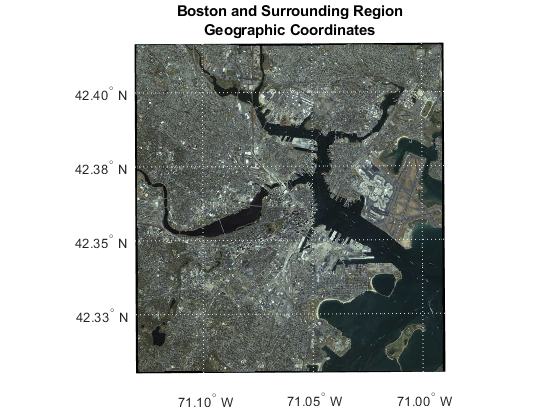

figure('Renderer', 'opengl')
ax = axesm(mstruct, 'Grid', 'on',...
    'GColor', [.9 .9 .9], ...
    'MapLatlimit', latlim, 'MapLonLimit', lonlim, ...
    'ParallelLabel', 'on', 'PLabelLocation', .025, 'PlabelMeridian', 'west', ...
    'MeridianLabel', 'on', 'MlabelLocation', .05, 'MLabelParallel', 'south', ...
    'MLabelRound', -2, 'PLabelRound', -2, ...
    'PLineVisible', 'on', 'PLineLocation', .025, ...
    'MLineVisible', 'on', 'MlineLocation', .05);
geoshow(overview, overviewR)
axis off
tightmap
title({'Boston and Surrounding Region', 'Geographic Coordinates'})

Since the coordinates of the GeoTIFF image are in a projected coordinate reference system, use `mapshow` to overlay the more detailed Boston image onto the display. Plot the boundaries of the Boston image in red.

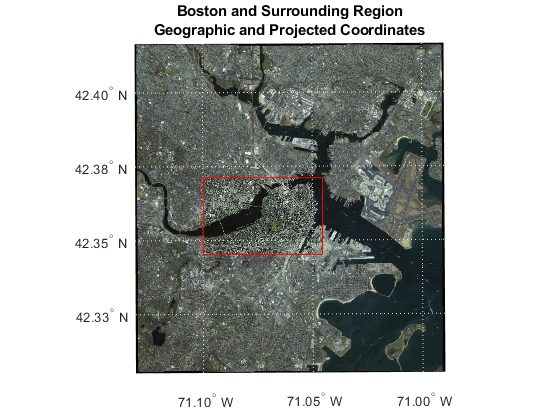

mapshow(boston, R)
plot(R.XWorldLimits([1 1 2 2 1]), R.YWorldLimits([1 2 2 1 1]), 'Color', 'red')
title({'Boston and Surrounding Region', 'Geographic and Projected Coordinates'})

Zoom to the geographic region of the GeoTIFF image by setting the axes limits to the limits of the Boston image and add a small buffer. Note that the buffer size (`delta`) is expressed in meters.

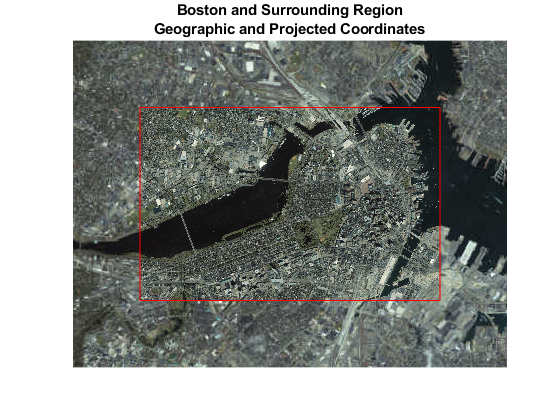

delta = 1000;
xLimits = R.XWorldLimits + [-delta delta];
yLimits = R.YWorldLimits + [-delta delta];
xlim(ax,xLimits)
ylim(ax,yLimits)
setm(ax, 'Grid', 'off');

You can overlay the road vectors onto the map display. Use a symbol specification to give each class of road its own color.

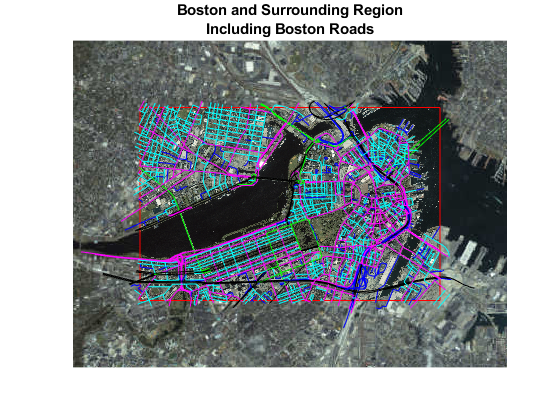

roadColors = makesymbolspec('Line',...
    {'CLASS', 2, 'Color', 'k'}, ...
    {'CLASS', 3, 'Color', 'g'},...
    {'CLASS', 4, 'Color', 'magenta'}, ...
    {'CLASS', 5, 'Color', 'cyan'}, ...
    {'CLASS', 6, 'Color', 'b'},...
    {'Default',  'Color', 'k'});
mapshow(roads, 'SymbolSpec', roadColors)
title({'Boston and Surrounding Region','Including Boston Roads'})

You can also overlay data from a GPS stored in a GPX file. Import point geographic vector data from the `boston_placenames.gpx` file included with the Mapping Toolbox™ software. The file contains latitude and longitude coordinates of geographic point features in part of Boston, Massachusetts, USA. Use `gpxread` to read the GPX file and return a `geopoint vector`. 

placenames = gpxread('boston_placenames')

placenames =  13×1 geopoint vector with properties:

 Collection properties:
       Geometry: 'point'
       Metadata: [1×1 struct]
 Feature properties:
       Latitude: [42.3501 42.3515 42.3598 42.3584 42.3529 42.3626 42.3668 42.3668 42.3668 42.3557 42.3557 42.3562 42.3459]
      Longitude: [-71.0870 -71.0926 -71.0662 -71.0598 -71.0662 -71.0789 -71.0995 -71.0564 -71.0801 -71.0662 -71.0495 -71.0662 -71.0564]
           Name: {''BACK BAY''  'BACK BAY FENS'  'BEACON HILL'  'BOSTON'  'BOSTON NECK'  'BROAD CANAL'  'CAMBRIDGE'  'COPPS HILL'  ''EAST CAMBRIDGE''  'FLAGSTAFF HILL'  'FORT POINT CHANNEL'  'FROG POND'  'SOUTH BAY'}
    Description: {'PPL-SUBDVSN'  'MARSH'  'HILL'  'PPL'  'PENINSULA'  'CANAL'  'PPL'  'HILL'  'PPL-SUBDVSN'  'HILL'  'CHANNEL'  'LAKE'  'INLET'}


Overlay the placenames onto the map and increase the marker size, change the markers to circles and set their edge and face colors to yellow.

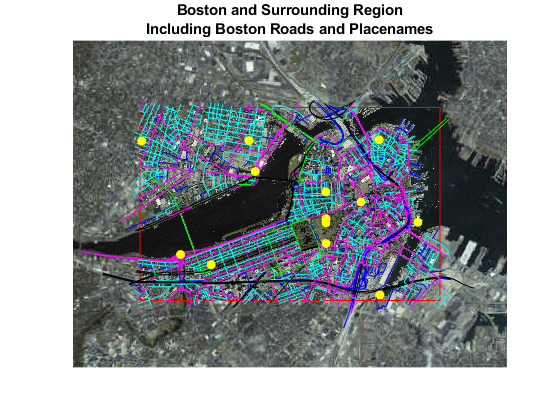

geoshow(placenames, 'Marker','o', 'MarkerSize', 6, ...
    'MarkerEdgeColor', 'y', 'MarkerFaceColor','y')
title({'Boston and Surrounding Region','Including Boston Roads and Placenames'})

## Credits

boston.tif, boston_ovr.jpg:

`  Copyright GeoEye `

`  Includes material copyrighted by GeoEye, all rights reserved.`

`  (GeoEye was merged into the DigitalGlobe corporation January 29th,`

`  2013.)`

`  For more information, run: `

`  >> type boston.txt`

`  >> type boston_ovr.txt`

boston_roads.shp, boston_placenames.gpx:

`  Office of Geographic and Environmental Information (MassGIS),`

`  Commonwealth of Massachusetts  Executive Office of Environmental Affairs`

`  http://www.state.ma.us/mgis`

`  For more information, run: `

`  >> type boston_roads.txt`

`  >> type boston_placenames_gpx.txt`

*Copyright 2013-2014 The MathWorks, Inc.*